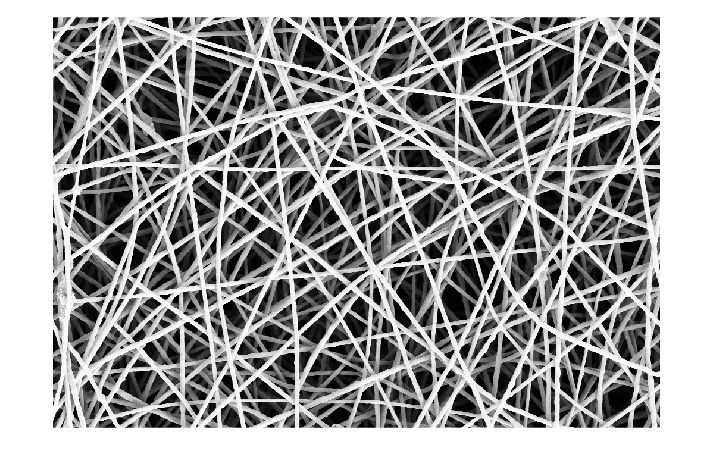

% Demo file for the sparse representation based anomaly detector

clear
close all
%addpath('functions')

seed = 1234;
rng(seed)
%% Set all the paramters for the anomaly detection
% patch size (tha patch is square)
p = 15;

% number of patches in the training set for dictionary learning
npatch_S = 10000;

% number of patches to estimate the confidence region
npatch_V = 1000;

% number of patches to estimate the threshold
npatch_T = 1000;


% paramters for the dictionary learning using the KSVD
niter_ksvd = 5;
natom = round(p^2*1.5);
L = 4;

% regularization parameters for the l1 sparse coding 
lambda = 0.08;

%% build the training set
% load the training image
img = im2double(imread('data/img_normal.png'));
figure(), imshow(img)


%% Extract random patches from the image and store them in a matrices S, V, T
patches_matrix = zeros([size(img,1)-p+1, size(img,2)-p+1]);% this matrix will be populated with ones that represent the top left corner position
% of each patch
indexes = randperm((size(img,1)-p)*(size(img,2)-p), npatch_S + npatch_V + npatch_T);
S_indexes = indexes(1:npatch_S);
V_indexes = indexes(npatch_S+1:npatch_S+npatch_V);
T_indexes = indexes(npatch_S+npatch_V+1:end);

S = zeros(p^2, npatch_S);
V = zeros(p^2, npatch_V);
T = zeros(p^2, npatch_T);
for i = 1:max([npatch_S, npatch_V, npatch_T])
    if i <= npatch_S
        [row,col] = ind2sub(size(patches_matrix),S_indexes(i));
        S(:,i) = reshape(img(row:row+p-1,col:col+p-1),[],1);
    end
    if i <= npatch_V
        [row,col] = ind2sub(size(patches_matrix),V_indexes(i));
        V(:,i) = reshape(img(row:row+p-1,col:col+p-1),[],1);
    end
    if i <= npatch_T
        [row,col] = ind2sub(size(patches_matrix),T_indexes(i));
        T(:,i) = reshape(img(row:row+p-1,col:col+p-1),[],1);
    end
end

%% Dictionary learning
% PREPROCESSING: exclude black patches from S
thr_black_patches = 0.06;
v = median(S,1);
S = S(:,v > thr_black_patches);

% PREPROCESSING: remove the mean from each patch
S = S - mean(S);

% dictionary learning using ksvd
algorithm = "OMP_Chol"

algorithm = "OMP_Chol"

tic
D1 = ksvd(S, natom, L, niter_ksvd, algorithm);

Using Ksvd with OMP_Chol...


toc

Elapsed time is 38.747255 seconds.


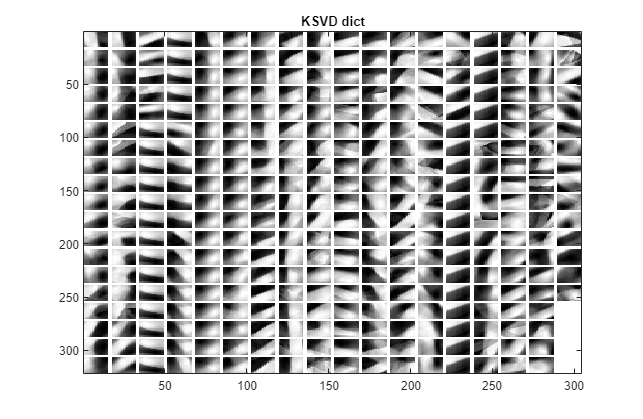

%% dictionary learning using mod
%algorithm = "IRLS"
%tic
%D2 = mod_dl(S, natom, lambda, niter_ksvd, algorithm);
%toc
%The mod algorithm is very time consuming

%%
show_dictionary(D1), title('KSVD dict')

%show_dictionary(D2), title('MOD dict')

D = D1;

%% Confidence region estimation / density estimation
% PREPROCESSING: exclude black patches
v = median(V,1);
V = V(:,v > thr_black_patches);

% PREPROCESSING: remove the mean from each patch
V = V - mean(V);
% sparse coding
X = zeros(size(D, 2), size(V, 2));
rho = 1;
inverse_matrix = 1/rho * eye(size(D,2)) - 1/rho*D'*((eye(size(D,1))*rho + D*D')\D);

for i = 1:size(V,2)
    %ell1 sparse coding
    X(:,i) = ADMM(D, V(:,i), 1, lambda, 1,inverse_matrix,   1e3, 1e-3);
    
    %ell0 sparse coding
    %X(:,i) = OMP(D, V(:,i), 1e-3, L);
    %X(:, i) = OMP_Chol(V(:,i), D, L, 1e-3);  
    %X(:, n) = MP(D, V(:,i), 1e-3, L, 100);
end

% computing the anomaly indicators (l1 norm, reconstruction error) for each
% patch in V
l1_norms = vecnorm(X, 1);
reconstruction_errors = vecnorm(V - D*X, 2);
V_tilde(1,:) = l1_norms;
V_tilde(2,:) = reconstruction_errors;
%V_tilde = 0.5*reconstruction_errors + lambda*l1_norms;
% DISTIBUTION FITTING: Model normal  estimation of mean and covariance 
% Use the patches in V
mu = mean(V_tilde,2);
Sigma = cov(V_tilde');

%% THRESHOLD ESTIMATION: estimation of the threshold that gives the desired false positive rate
% using the patches in T
% PREPROCESSING: exclude black patches
v = median(T,1);
T = T(:,v > thr_black_patches);
% PREPROCESSING: remove the mean from each patch
T = T - mean(T);

%%
% compute the value of the anomaly score for each of the patches
% sparse coding
X_T = zeros(size(D, 2), size(T, 2));
for i = 1:size(T,2)
    %ell1 sparse coding
    X_T(:,i) = ADMM(D, T(:,i), 1, lambda, 1,inverse_matrix,   1e3, 1e-3);
    %ell0 sparse coding 
    %X_T(:,i) = OMP(D, T(:,i), lambda, L);
    %X_T(:, i) = OMP_Chol(T(:,i), D, L, 1e-3);  
    %X_T(:, i) = MP(D, T(:,i), 1e-3, L, 100);
end

l1_norms_T = vecnorm(X_T, 1);
reconstruction_errors_T = vecnorm(T - D*X_T, 2);
anomaly_score_T = lambda*l1_norms_T + reconstruction_errors_T/2;

T_tilde(1,:) = l1_norms_T ;
T_tilde(2,:) = reconstruction_errors_T ;
%T_tilde = 0.5*reconstruction_errors_T + lambda*l1_norms_T;
sigmainv = inv(Sigma);

%mahalanobis distance between Test_tilde and mu wrt matrix Sigma
A_T = sum(((T_tilde - mu)'*sigmainv).*(T_tilde - mu)', 2);
A_T = A_T';


% set the threshold
FPR_target = 0.1;
threshold = quantile(A_T', 1-FPR_target);


%% Test phase
STEP = 1; %1 for overlapping patches and max performances
% load the test image
img = im2double(imread('data/img_anom.png'));
% extract non-overlapping patches and store them in a matrix S
S_test = zeros(p*p, ((size(img,1)-p+1)/STEP)*(size(img,2)-p+1)/STEP); %there will be a lot of null cols but no problem
k = 1;
for i=1:STEP:(size(img,1)-p+1)/STEP
    for j = 1:STEP:(size(img,2)-p+1)/STEP
        S_test(:,k)= reshape(img(i:i+p-1,j:j+p-1),[],1);
        k = k+1;
    end
end
% find the black patches, that are normal
v = median(S_test,1);
index_black = find(v<=thr_black_patches);

% remove the mean value for each patch
S_test = S_test- mean(S_test);
% sparse coding 
X_test = zeros(size(D, 2), size(S_test, 2));
zz = 1;
for i = 1:STEP:(size(img,1)-p+1)/STEP
    for j = 1:STEP:(size(img,2)-p+1)/STEP
        %ell1 sparse coding
        X_test(:,zz) = ADMM(D, S_test(:,zz), 1, lambda, rho,inverse_matrix,   1e3, 1e-3);
        
        %ell0 sparse coding
        %X_test(:,zz) = OMP(D, S_test(:,zz), 0.001, L);
        %X_test(:, zz) = OMP_Chol(S_test(:,zz), D, L, 1e-3);  
        %X_test(:, zz) = MP(D,S_test(:,zz), 1e-3, L, 100);
        zz = zz+1;
    end
end
% computing the anomaly indicator
l1_norms_Test = vecnorm(X_test, 1);
reconstruction_errors_Test = vecnorm(S_test - D*X_test, 2);

Test_tilde = zeros(2,size(S_test,2));
Test_tilde(1,:) = l1_norms_Test ;
Test_tilde(2,:) = reconstruction_errors_Test ;
%Test_tilde = 0.5*reconstruction_errors_Test + lambda*l1_norms_Test;

sigmainv = inv(Sigma);
%mahalanobis distance between Test_tilde and mu wrt matrix Sigma
A_Test = sum(((Test_tilde - mu)'*sigmainv).*(Test_tilde - mu)', 2);
A_Test = A_Test';

% find the indicators that fall outside the confidence region
anomalies = find((A_Test>threshold'));


%%
% build the dection mask, that has the same size of the test image
% each pixel in the mask has value 1 if the corresponding patch has been
% detected as anomalous, otherwise it has value 0

idx_anomalies = sort(anomalies);
idx_black = sort(index_black);
mask = zeros(size(img));
weights = zeros(size(img));
k = 1;
idx_anom = 1;
idx_b = 1;

for i = 1:STEP:(size(img,1)-p+1)/STEP
    for j = 1:STEP:(size(img,2)-p+1)/STEP
        
        weights(i:i+p-1, j:j+p-1) = weights(i:i+p-1, j:j+p-1) + 1;
        
        
        if (k==idx_anomalies(idx_anom)) && not(k==idx_black(idx_b))
            mask(i:i+p-1, j:j+p-1) = mask(i:i+p-1, j:j+p-1) + 1;
            idx_anom = min(idx_anom + 1, size(idx_anomalies,2));
        else
            if (k==idx_black(idx_b))
                idx_b = min(idx_b + 1, size(idx_black,2));
            end
            if (k==idx_anomalies(idx_anom))
                idx_anom = min(idx_anom + 1, size(idx_anomalies,2));
            end
        end
        k = k+1;
    end
end

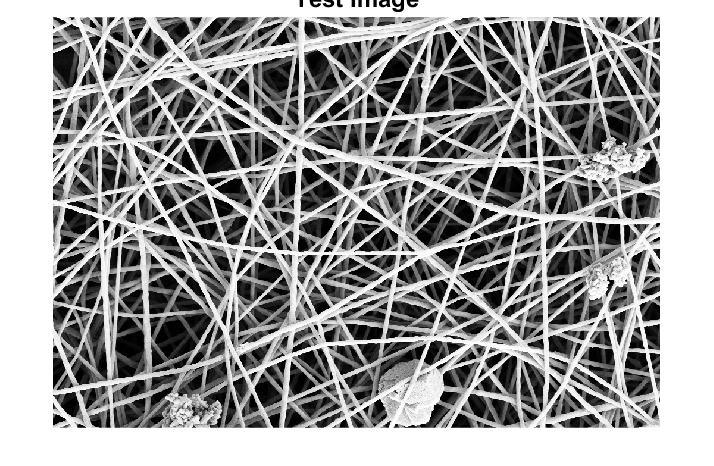



%% show the results
mask = mask./weights;
mask(mask>0.5) = 1;
mask(mask<=0.5) = 0;
figure(3), imshow(img), title('Test Image','FontSize',18)

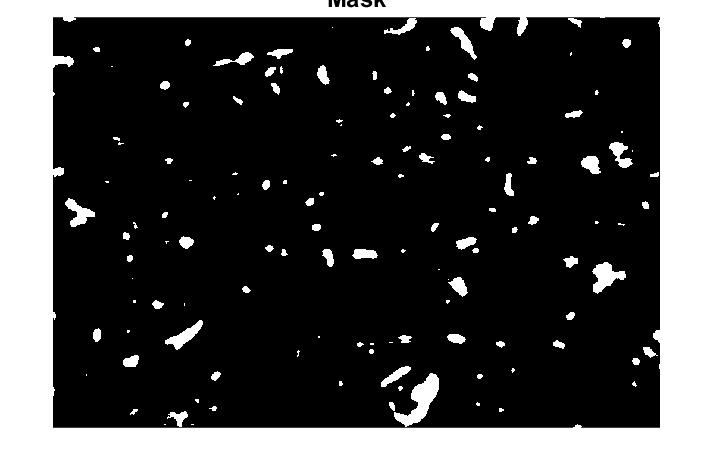

figure(4), imshow(mask), title('Mask','FontSize',18)

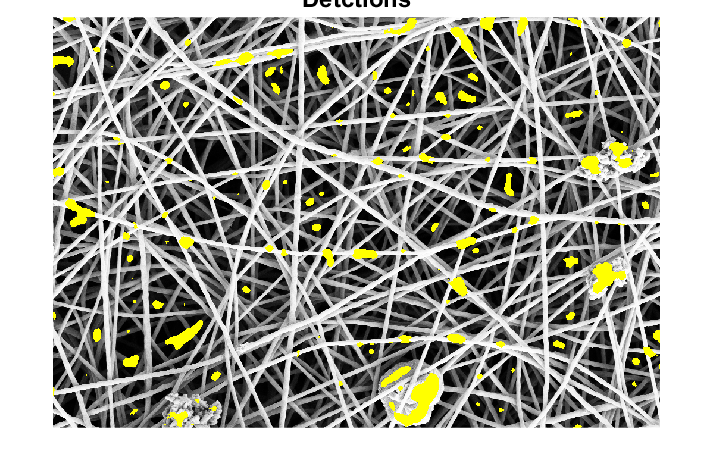


% combine the mask and the test image
img_color = zeros([size(img),3]);
img_temp = img;
img_temp(mask > 0) = 1;%1
img_color(:,:,1) = img_temp;
img_temp = img;
img_temp(mask > 0) = 1;
img_color(:,:,2) = img_temp;
img_temp = img;
img_temp(mask > 0) = 0;
img_color(:,:,3) = img_temp;

figure(5), imshow(img_color),title('Detctions','FontSize',18);

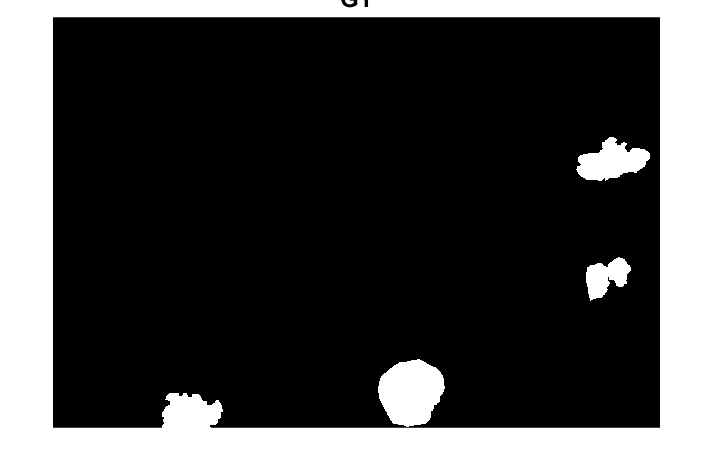


%% load the ground truth and compute the ROC curve
gt = imread('data/gt.png');
figure(5), imshow(gt),title('GT','FontSize',18);

% compute the false positive rate and true positive rate for several values
% of the threshold

FPR = sum(gt(mask>0)==0, "all")/(sum(gt(mask>0)==0, "all") + sum(gt(mask==0)==0, "all"))

FPR = 0.0293

TPR = sum(gt(mask>0)>0,  "all")/(sum(gt(mask>0)>0,"all") + sum(gt(mask==0)>0, "all"))

TPR = 0.3079


filename = "savings.txt"

filename = "savings.txt"

fid = fopen(filename, 'a');
if fid ~= -1
    fprintf(fid,'%f %f\n', [FPR TPR]);
    fclose(fid);
else
    warningMessage = sprintf('Cannot open file %s', filename);
    uiwait(warndlg(warningMessage));
end

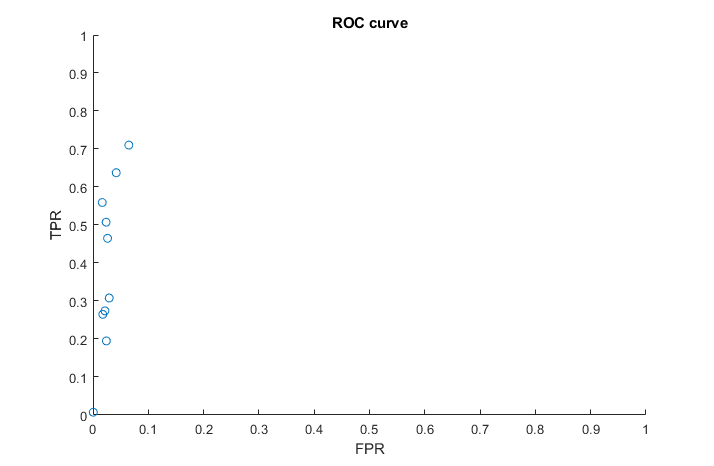

fid = fopen(filename, 'r');
A = fscanf(fid,"%f", [2 Inf]);
A = A';
% show the ROC curve by plotting the FPR against the TPR
scatter(A(:,1), A(:, 2))
xlim([0 1]);
ylim([0 1]);
xlabel('FPR');
ylabel('TPR');
title("ROC curve")

%the results with TPR>0.4 are obtained increasing the patch size to 25 and
%30 and using ell0 sparse coding (OMP).

%the results using patch size = 15 and in particular ell1 sparse coding are
%not as promising since admm is very slow and we should also tune the
%parameters rho and lambda

%% The best performances are obtained setting p = 30 and using ell0 sparse coding with OMP_Chol





